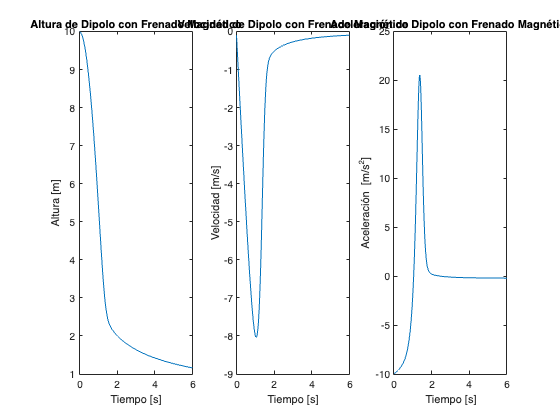

% Aceleración
grav = 9.81;

% Masa del dipolo
m = 0.01;

% es la permeabilidad máxima del MetGlass
mu = 1e6;

% Permeabilidad del espacio libre
mu_0 = 4 * pi * 1e-7;

% Radio del anillo de corriente
a = 0.08;

% Resistividad
R = 9e-5;

% Calculo constante k
% k = (9 * (mu * mu_0) ^ 2 * a ^ 4) / (4 * R);
k = (9 * (mu * mu_0) ^ 2 * a^4) / (4 * R);

% Funciones de posición y derivada
p = @(x) x .^ 2 ./ ((x .^ 2 + a .^ 2) .^ (5 / 2));
dp_dx = @(x) (10 * x .^ 2) ./ ((x .^ 2 + a .^ 2) .^ (7 / 2)) - (x .^ 2) ./ ((x .^ 2 + a .^ 2) .^ (5 / 2));

% Ecuaciones de movimiento
f = @(t, x, y) y;
g = @(t, x, y) -grav - (k / m) * p(x) .* y;
dg_dt = @(t, x, y) (dp_dx(x) .* -(y .^ 2) - (k / m) * p(x) .* y) - 10;

% Tiempo inicial y final
t_0 = 0;
t_f = 6;

% Altura inicial x_0 y velocidad inicial y_0
x_0 = 10;
y_0 = 0;

% Paso horizontal
h = 0.01;

% Número de pasos
N = round((t_f - t_0) / h);

% Arreglo con valores del tiempo
t = linspace(t_0, t_f, N);

all_xs = [];
all_ys = [];
all_as = [];

% Usar los valores iniciales para el primer paso
x_n = x_0;
y_n = y_0;

% Iterar para cada paso de la lista de tiempo t
for i = 1:N
    t_n = t(i);

    % Calcular k's
    kx1 = f(t_n, x_n, y_n);
    ky1 = g(t_n, x_n, y_n);

    kx2 = f(t_n + 0.5 * h, x_n + 0.5 * h * kx1, y_n + 0.5 * h * ky1);
    ky2 = g(t_n + 0.5 * h, x_n + 0.5 * h * kx1, y_n + 0.5 * h * ky1);

    kx3 = f(t_n + 0.5 * h, x_n + 0.5 * h * kx2, y_n + 0.5 * h * ky2);
    ky3 = g(t_n + 0.5 * h, x_n + 0.5 * h * kx2, y_n + 0.5 * h * ky2);

    kx4 = f(t_n + h, x_n + h * kx3, y_n + h * ky3);
    ky4 = g(t_n + h, x_n + h * kx3, y_n + h * ky3);

    % Calcular x_nplus1 y y_nplus1
    x_nplus1 = x_n + (1 / 6) * h * (kx1 + 2 * kx2 + 2 * kx3 + kx4);
    y_nplus1 = y_n + (1 / 6) * h * (ky1 + 2 * ky2 + 2 * ky3 + ky4);

    % Guardar valores calculados
    all_xs(i) = x_nplus1;
    all_ys(i) = y_nplus1;

    % Actualizar x_n y y_n
    x_n = x_nplus1;
    y_n = y_nplus1;

    % Calcular aceleración usando la velocidad actual
    a_n = dg_dt(t_n, x_n, y_n);

    % Guardar aceleración calculada
    all_as(i) = a_n;
end

% Graficar resultados
figure;
subplot(1, 3, 1);
plot(t, all_xs);
title('Altura de Dipolo con Frenado Magnético');
xlabel('Tiempo [s]');
ylabel('Altura [m]');

subplot(1, 3, 2);
plot(t, all_ys);
title('Velocidad de Dipolo con Frenado Magnético');
xlabel('Tiempo [s]');
ylabel('Velocidad [m/s]');

subplot(1, 3, 3);
plot(t, all_as);
title('Aceleración de Dipolo con Frenado Magnético');
xlabel('Tiempo [s]');
ylabel('Aceleración [m/s^2]');